# NLP: an analysis for fund classification based on intorduction textual data

clc;
clear all;
close all;
% make sure the result is reproducible
rng(42);


%%%%% read data

% summaries are stored in a folder 
% contains all the .txt files
summary_path = "MutualFundSummary";

% corresponding classification labels are in
% a .txt file
labels_path = "MutualFundLabels.csv";

% read labels
tab_labels = readtable(labels_path, ...
    "VariableNamingRule","modify");

% read files from the folder
list_summaries = dir(summary_path);
% delete first 2 meaningless hidden files
list_summaries = list_summaries(3:end);
% create "empty" arries for strings
summaries = [""];
fund_names = [""];
% traverse the list of files to read
for i = 1:length(list_summaries)
    fileID = fopen(summary_path+...
            "/"+list_summaries(i).name, ...
            'r');
    formatSpec = "%c";
    % read the whole .txt file as a char string
    char_read = fscanf(fileID,formatSpec);
    split_txt = split(char_read,"<head_breaker>");
    fund_names(end+1) = convertCharsToStrings(...
            strip(split_txt{1,1}));
    summaries(end+1) = convertCharsToStrings(...
        strip(split_txt{2,1}));
end

summaries = summaries(2:end);
fund_names = fund_names(2:end);
% store origin
origin_summaries = summaries;

%%%%% Vectorization of words
% we will build a embedding dictionary to
% map textual data into the vectors

%%% Preprocessing the data set
% tokenize the strings
summaries = tokenizedDocument(summaries);
% remove new line return and carriage returns
% (Only works for Windows system)
summaries = regexprep(summaries,'[\n\r]+','');
% get lower case of the string
summaries = lower(summaries);
% erace the punctuations in the string
summaries = erasePunctuation(summaries);
% remove some other meaningless symbols
list_symbols = ["[","]","*","''",...
                  "doe","ha","wa"];
summaries = removeWords(summaries,list_symbols);
% remove stop words in the strings
summaries = removeStopWords(summaries);
% remove everything that is not an English letter
summaries = regexprep(summaries,'[^a-zA-Z\s]','');



%%% build a word embedding dictionary
% with embedding dictionary, we should be
% able to translate the words into vectors


emb = trainWordEmbedding(summaries, ...
    "LossFunction","ns", ...
    "Model","skipgram");

Training: 100% Loss: 1.58063  Remaining time: 0 hours 0 minutes.


% visuralize the words embedding dict
words = emb.Vocabulary;
V = word2vec(emb,words);
XY = tsne(V);
textscatter(XY,words)

%%%% build knowledge bases
% for each type ("y") variale, we would
% like to get a set of some words that 
% could "represent" this type closely.

% join 2 tables wrt./ "fund_name"
data_tab = table(fund_names', summaries', ...
    origin_summaries');
data_tab.Properties.VariableNames = [...
    "fund_name",
    "summary",
    "origin_summary"];
% change the data type of key column
% to make sure join operation is possible
tab_labels.fund_name = string( ...
    tab_labels.fund_name);
data_tab.fund_name = string( ...
    data_tab.fund_name);
data = innerjoin(tab_labels, ...
    data_tab, ...
    "Keys","fund_name");
% only use these 4 columns
data = data(:,["fund_name",...
    "summary",...
    "origin_summary",...
    "IvestmentStrategy"]);
data.IvestmentStrategy = string( ...
    data.IvestmentStrategy);
% find all catagories of investment strategies
strategies = unique(data.IvestmentStrategy);
% show the distribution of "y": objectives
number = ones(length(strategies),1);
tab_objs = table(number, strategies);
for i = 1:length(strategies)
    strtg = tab_objs.strategies(i);
    tab_objs.number(i) = sum( ...
        data.IvestmentStrategy == strtg);
end
tab_objs

tab_objs = 5×2 table
    number                strategies             
    ______    ___________________________________

      84      "Balanced Fund (Low Risk)"         
       1      "Commodities Fund (Low Risk)"      
     247      "Equity Long Only (Low Risk)"      
     130      "Fixed Income Long Only (Low Risk)"
       4      "Long Short Funds (High Risk)"     


% delete the "Commodities Fund (Low Risk)"
% b/c only 1 observation recorded.
tab_objs = tab_objs( ...
    tab_objs.strategies ...
    ~= "Commodities Fund (Low Risk)",:);
data = data( ...
  data.IvestmentStrategy ~= ...
  "Commodities Fund (Low Risk)",:);
% get the 30 most common words as the fundamental of
% "knowledge base" for each type
dict_most_common  = dictionary;
for i = 1:height(tab_objs)
    strtg = tab_objs.strategies(i);
    data_strtg = data( ...
        data.IvestmentStrategy == ...
        strtg,:);
    bag = bagOfWords(data_strtg.summary);
    % bag words
    top_words = topkwords(bag, 30);
    % update the dictionary
    dict_most_common(string(strtg)) =...
        {top_words.Word};
end
% get 5 closest words in embedding dictionary
% to construct knowledge bases for each type
k = 5;% number of neighbor words
dict_knowledge_bases = dictionary;
for i = 1:height(tab_objs)
    strtg = tab_objs.strategies(i);
    common_words = dict_most_common(strtg);
    % extract the words array out of the cell
    common_words = common_words{1,1};
    neighbor_words = [];
    for j = 1:length(common_words)
        word = common_words(j);
        % get the closest 5 words in 
        % embedding dictionary if the word 
        % is in the embedding dictionary
        if isVocabularyWord(emb,word)
            [words,dist] = vec2word( ...
                emb,word2vec(emb,word), ...
                5,'Distance','cosine');
            neighbor_words = unique( ...
                [neighbor_words; words]);
        else
            % otherwise if not in, just skip
            continue
        end
    end
    % the following gurantee the knowledge 
    % bases must be included in embedding
    % dictionary.
    dict_knowledge_bases( ...
        string(strtg)) = {...
        unique(neighbor_words)};
end

%%%% vectorization of summaries(construct X)
% before we already get the embedding
% dictionary to be able to vectorize
% each words. Now we try to evaluate
% (vectorize) each record of summary.
% (ATTENTION: THIS BLOCK WILL TAKE ABOUT 30MINS TO RUN

X = [];
for i = 1:height(data)% each fund
    fprintf('%d ', i);% just to check the speed
    summary = data{i,"origin_summary"};
    sents = [];
    for j = 1:height(tab_objs)% each type
        strategy = tab_objs.strategies(j);
        knowledge_cell = dict_knowledge_bases(strategy);
        knowledge = knowledge_cell{1,1};
        sents = unique([sents; extract_sentences_distances( ...
            summary,knowledge, 10, 5, 5,emb)]);
    end
    X = [X; join(sents, " ")];
end

1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 

%%%% save X to avoid re-run of 30-min block
%%%% and read X from saved file
% save('apr29','X');
% S = load('apr29');

%%%% Convert X to numeric data
% we adopted the 'berttokenizer' directly

X_tokenized = tokenize(X);
X_bag = bagOfWords(X_tokenized);
X_top_words = topkwords(bag, 400);
% train a berttokenizer based on the tokenizer

X_vocab = [X_top_words.Word ;"[PAD]";...
    "[CLS]"; "[UNK]"; "[SEP]"]';
bert_tokenizer = bertTokenizer(X_vocab);

X_numeric = [];
x_template = ones(1,400);

for i = 1:length(X)
	[tokencodes, segments] = encode(bert_tokenizer, X(i));
    token_arr = tokencodes{1,1};
    token_arr = token_arr(token_arr<=400);
    if length(token_arr) < 400
        token_arr(numel(x_template)) = 0;
	    X_numeric = [X_numeric;token_arr];
    else
        X_numeric = [X_numeric;...
            token_arr(1:400)];
    end
end
% reduce the # of columns of numeric matrix
% to improve computation efficiency
[nrow, ncol] = size(X_numeric);
n_nonzero = zeros(nrow,1);
for i = 1:nrow
    x = X_numeric(i,:);
    n_nonzero(i) = sum(x~=0);
end
X_numeric = X_numeric(:,1:max(n_nonzero));

%%%% encode of y(construct y)
% just encode the 4 classes as 
% [1,2,3,4] correspondingly.
y_numeric = ones(height(data),1);
classes = tab_objs{:,"strategies"};

for i = 1:height(data)
    y_numeric(i) = 0*(data.IvestmentStrategy(i) == classes(1))+...
        1*(data.IvestmentStrategy(i) == classes(3))+...
        2*(data.IvestmentStrategy(i) == classes(2))+...
        3*(data.IvestmentStrategy(i) == classes(4));
end

% Display the mapping between actual words and encoded numeric values
for i = 1:numel(classes)
    fprintf('Class %d: %s -> Numeric Value: %d\n', i, classes{i}, i);
end

Class 1: Balanced Fund (Low Risk) -> Numeric Value: 1
Class 2: Equity Long Only (Low Risk) -> Numeric Value: 2
Class 3: Fixed Income Long Only (Low Risk) -> Numeric Value: 3
Class 4: Long Short Funds (High Risk) -> Numeric Value: 4


%%%% save all the variables to save runtime
save("numeric_vars");
load("numeric_vars");

rng(1)
% Split X_numeric, y_numeric into train(60%) validation(20%) test(20%) set.

cvp = cvpartition(size(y_numeric, 1), 'HoldOut', 0.4);
idxTrain = training(cvp);
idxTempTest = test(cvp);

cvpTest = cvpartition(sum(idxTempTest), 'HoldOut', 0.5);

idxValidationRelative = training(cvpTest);
idxTestRelative = test(cvpTest);

idxValidation = idxTempTest;
idxTest = idxTempTest;
idxValidation(find(idxTempTest)) = idxValidationRelative;
idxTest(find(idxTempTest)) = idxTestRelative;

X_train = X_numeric(idxTrain, :);
y_train = y_numeric(idxTrain);

X_validation = X_numeric(idxValidation, :);
y_validation = y_numeric(idxValidation);

X_test = X_numeric(idxTest, :);
y_test = y_numeric(idxTest);

% Change y_train, validation, and test into categorical.
if ~iscategorical(y_train)
    y_train = categorical(y_train);
end

if ~iscategorical(y_validation)
    y_validation = categorical(y_validation);
end

if ~iscategorical(y_test)
    y_test = categorical(y_test);
end

## Linear Discriminant Analysis

% Combine train and validation set together as validation set is not needed
% in LDA
X_train_all = [X_train; X_validation];
y_train_all = [y_train; y_validation];

% Fit LDA model
ldaModel = fitcdiscr(X_train_all, y_train_all, 'DiscrimType', 'pseudoLinear');

% Prediction on train set
YTrainPred = predict(ldaModel, X_train_all);

% Calculate Accuracy, Precision, Recall, F1-Score for train set 
trainAccuracy = sum(YTrainPred == y_train_all) / numel(y_train_all);
fprintf('LDA Training Set Accuracy: %.2f%%\n', trainAccuracy * 100);

LDA Training Set Accuracy: 94.89%



confMatTrain = confusionmat(y_train_all, YTrainPred);

precisionTrain = diag(confMatTrain) ./ sum(confMatTrain, 2);
recallTrain = diag(confMatTrain) ./ sum(confMatTrain, 1)';
f1ScoreTrain = 2 * (precisionTrain .* recallTrain) ./ (precisionTrain + recallTrain);

fprintf('\nLDA Training Set Metrics:\n');


LDA Training Set Metrics:


for i = 1:length(precisionTrain)
    fprintf('Class %d - Precision: %.2f, Recall: %.2f, F1 Score: %.2f\n', ...
        i, precisionTrain(i), recallTrain(i), f1ScoreTrain(i));
end

Class 1 - Precision: 0.91, Recall: 0.98, F1 Score: 0.95
Class 2 - Precision: 0.92, Recall: 0.96, F1 Score: 0.94
Class 3 - Precision: 0.97, Recall: 0.93, F1 Score: 0.95
Class 4 - Precision: 1.00, Recall: 1.00, F1 Score: 1.00



% Prediction on test set
YTestPred = predict(ldaModel, X_test);

% Calculate Accuracy, Precision, Recall, F1-Score for test set 
testAccuracy = sum(YTestPred == y_test) / numel(y_test);
fprintf('LDA Test Set Accuracy: %.2f%%\n', testAccuracy * 100);

LDA Test Set Accuracy: 59.14%


confMatTest = confusionmat(y_test, YTestPred);

precisionTest = diag(confMatTest) ./ sum(confMatTest, 2);
recallTest = diag(confMatTest) ./ sum(confMatTest, 1)';
f1ScoreTest = 2 * (precisionTest .* recallTest) ./ (precisionTest + recallTest);

fprintf('\nLDA Test Set Metrics:\n');


LDA Test Set Metrics:


for i = 1:length(precisionTest)
    fprintf('Class %d - Precision: %.2f, Recall: %.2f, F1 Score: %.2f\n', ...
        i, precisionTest(i), recallTest(i), f1ScoreTest(i));
end

Class 1 - Precision: 0.40, Recall: 0.43, F1 Score: 0.41
Class 2 - Precision: 0.45, Recall: 0.57, F1 Score: 0.50
Class 3 - Precision: 0.73, Recall: 0.75, F1 Score: 0.74
Class 4 - Precision: NaN, Recall: 0.00, F1 Score: NaN


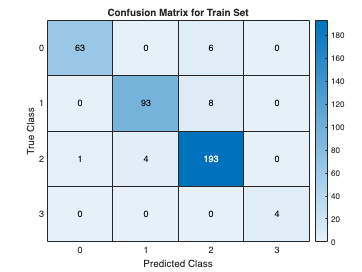

confMatTest = confusionmat(y_train_all, YTrainPred);
% Get all unique categories
allCategories = unique(y_train_all);

% Plot confusion matrix
figure; 
g = heatmap(allCategories, allCategories, confMatTest);

% Set heatmap properties
g.Title = 'Confusion Matrix for Train Set';
g.XLabel = 'Predicted Class';
g.YLabel = 'True Class';
g.ColorbarVisible = 'on';
g.FontSize = 12; 
g.CellLabelFormat = '%d'; 

exportgraphics(g, 'LDA_cf_train.png', 'Resolution', 300);

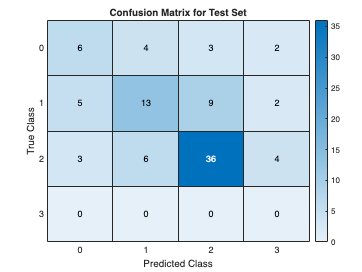

confMatTest = confusionmat(y_test, YTestPred);
% Print Confusion Matrix
allCategories = categories(y_train_all); 

confMatTest = confusionmat(categorical(y_test, allCategories), categorical(YTestPred, allCategories));


figure; 
h = heatmap(allCategories, allCategories, confMatTest);

h.Title = 'Confusion Matrix for Test Set';
h.XLabel = 'Predicted Class';
h.YLabel = 'True Class';
h.ColorbarVisible = 'on';

h.FontSize = 12; 
h.CellLabelFormat = '%d'; 
exportgraphics(h, 'LDA_cf_test.png', 'Resolution', 300);

## Quadratic Discriminant Analysis

% Combine train and validation set together as validation set is not needed
% in QDA
X_train_all = [X_train; X_validation];

y_train_all = [y_train; y_validation];
qdaModel = fitcdiscr(X_train_all, y_train_all, 'DiscrimType', 'diagQuadratic');

% Prediction on train set
YTrainPred = predict(qdaModel, X_train_all);

% Calculate Accuracy, Precision, Recall, F1-Score for train set 
trainAccuracy = sum(YTrainPred == y_train_all) / numel(y_train_all);
fprintf('QDA Training Set Accuracy: %.2f%%\n', trainAccuracy * 100);

QDA Training Set Accuracy: 53.23%




confMatTrain = confusionmat(y_train_all, YTrainPred);

precisionTrain = diag(confMatTrain) ./ sum(confMatTrain, 2);
recallTrain = diag(confMatTrain) ./ sum(confMatTrain, 1)';
f1ScoreTrain = 2 * (precisionTrain .* recallTrain) ./ (precisionTrain + recallTrain);

fprintf('\nQDA Training Set Metrics:\n');


QDA Training Set Metrics:


for i = 1:length(precisionTrain)
    fprintf('Class %d - Precision: %.2f, Recall: %.2f, F1 Score: %.2f\n', ...
        i, precisionTrain(i), recallTrain(i), f1ScoreTrain(i));
end

Class 1 - Precision: 0.00, Recall: NaN, F1 Score: NaN
Class 2 - Precision: 0.00, Recall: NaN, F1 Score: NaN
Class 3 - Precision: 1.00, Recall: 0.53, F1 Score: 0.69
Class 4 - Precision: 0.00, Recall: NaN, F1 Score: NaN


% Prediction on test set
YTestPred = predict(qdaModel, X_test);

% Calculate Accuracy, Precision, Recall, F1-Score for test set 
testAccuracy = sum(YTestPred == y_test) / numel(y_test);
fprintf('QDA Test Set Accuracy: %.2f%%\n', testAccuracy * 100);

QDA Test Set Accuracy: 52.69%



confMatTest = confusionmat(y_test, YTestPred);

precisionTest = diag(confMatTest) ./ sum(confMatTest, 2);
recallTest = diag(confMatTest) ./ sum(confMatTest, 1)';
f1ScoreTest = 2 * (precisionTest .* recallTest) ./ (precisionTest + recallTest);

fprintf('\nQDA Test Set Metrics:\n');


QDA Test Set Metrics:


for i = 1:length(precisionTest)
    fprintf('Class %d - Precision: %.2f, Recall: %.2f, F1 Score: %.2f\n', ...
        i, precisionTest(i), recallTest(i), f1ScoreTest(i));
end

Class 1 - Precision: 0.00, Recall: NaN, F1 Score: NaN
Class 2 - Precision: 0.00, Recall: NaN, F1 Score: NaN
Class 3 - Precision: 1.00, Recall: 0.53, F1 Score: 0.69
Class 4 - Precision: NaN, Recall: NaN, F1 Score: NaN


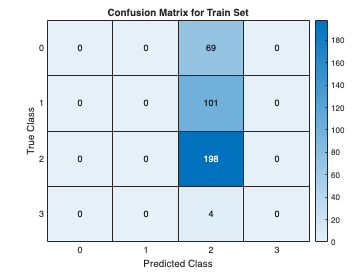

confMatTest = confusionmat(y_train_all, YTrainPred);
% Get all unique categories
allCategories = unique(y_train_all);

% Plot confusion matrix
figure; 
g = heatmap(allCategories, allCategories, confMatTest);

% Set heatmap properties
g.Title = 'Confusion Matrix for Train Set';
g.XLabel = 'Predicted Class';
g.YLabel = 'True Class';
g.ColorbarVisible = 'on';
g.FontSize = 12; 
g.CellLabelFormat = '%d'; 

exportgraphics(g, 'QDA_cf_train.png', 'Resolution', 300);

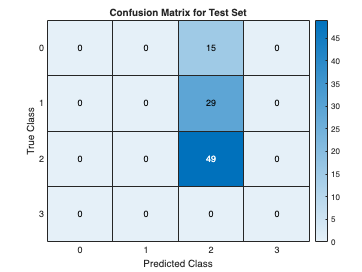

confMatTest = confusionmat(y_test, YTestPred);
% Print Confusion Matrix
allCategories = categories(y_train_all); 

confMatTest = confusionmat(categorical(y_test, allCategories), categorical(YTestPred, allCategories));


figure; 
h = heatmap(allCategories, allCategories, confMatTest);

h.Title = 'Confusion Matrix for Test Set';
h.XLabel = 'Predicted Class';
h.YLabel = 'True Class';
h.ColorbarVisible = 'on';

h.FontSize = 12; 
h.CellLabelFormat = '%d'; 
exportgraphics(h, 'QDA_cf_test.png', 'Resolution', 300);

## CNN

% Reshape X_train, validation, and test
[numSamples, numFeatures] = size(X_train);
X_train_reshaped = reshape(X_train', [1, numFeatures, 1, numSamples]);

[numSamplesVal, ~] = size(X_validation);
X_validation_reshaped = reshape(X_validation', [1, numFeatures, 1, numSamplesVal]);

[numSamplesTest, ~] = size(X_test);
X_test_reshaped = reshape(X_test', [1, numFeatures, 1, numSamplesTest]);

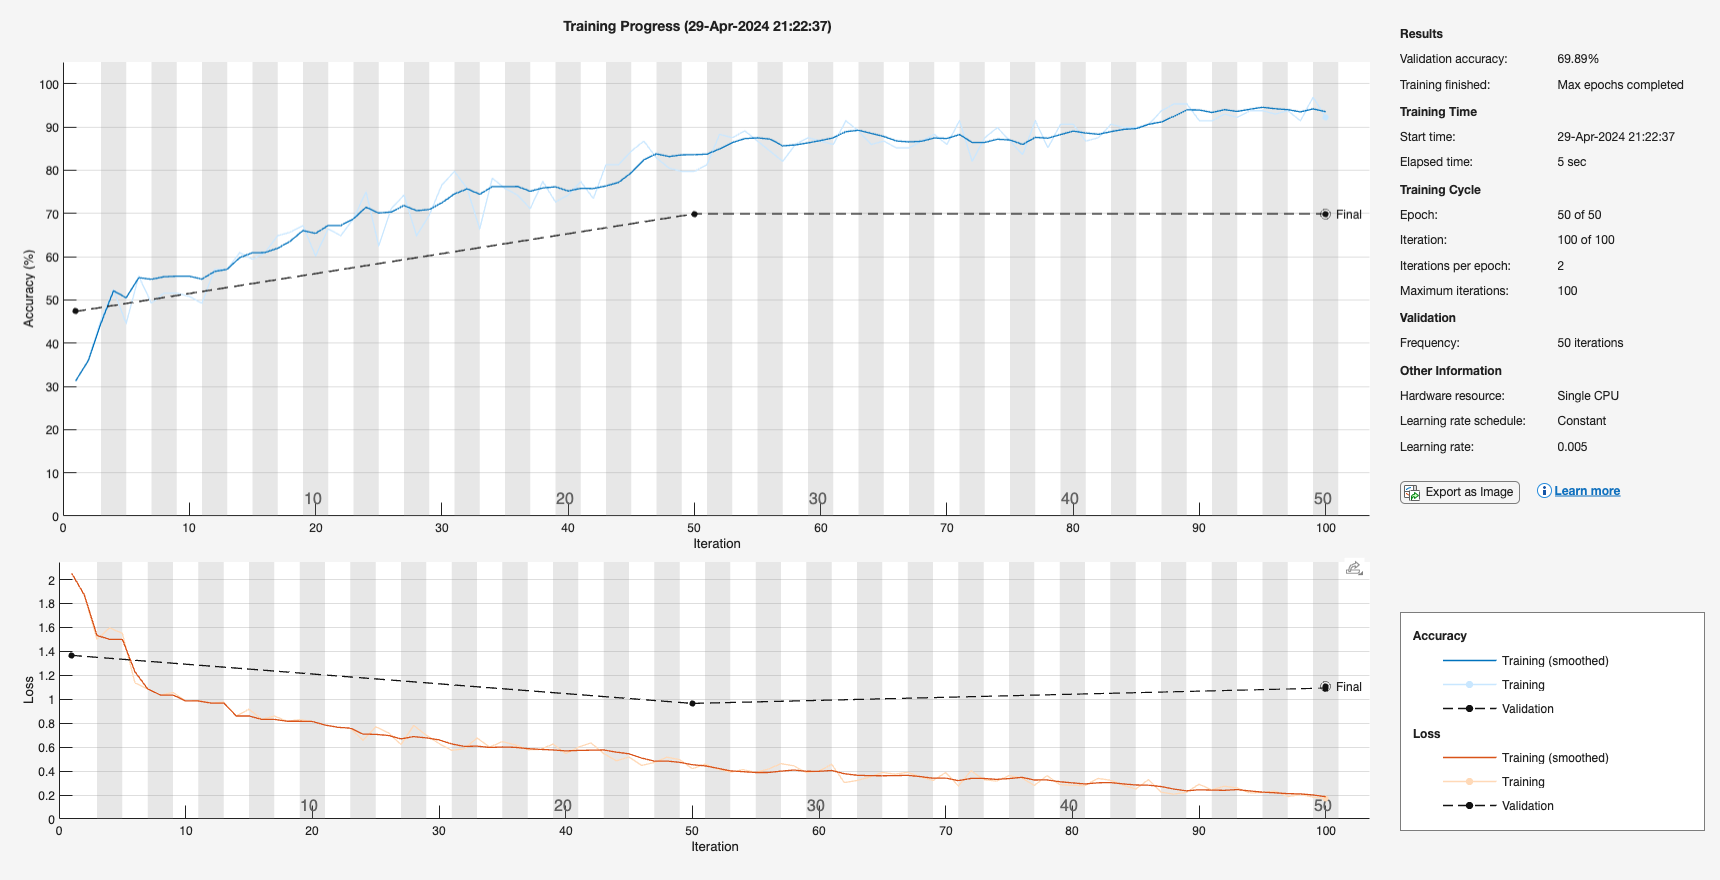

numFeatures = size(X_train, 2);  
numHiddenUnits = 100;            
numClasses = length(unique(y_train));  

% Define the CNN architecture
layers = [
    imageInputLayer([1 numFeatures 1],'Name','input','Normalization','none')
    
    convolution2dLayer([1 5], 64, 'Padding', 'same', 'Name', 'conv1')  
    batchNormalizationLayer('Name','BN1')
    reluLayer('Name','relu1')
    
    maxPooling2dLayer([1 2], 'Stride', [1 2], 'Name', 'maxpool1')
    
    convolution2dLayer([1 5], 32, 'Padding', 'same', 'Name', 'conv2')  
    batchNormalizationLayer('Name','BN2')
    reluLayer('Name','relu2')
    
    maxPooling2dLayer([1 2], 'Stride', [1 2], 'Name', 'maxpool2')
    
    flattenLayer('Name', 'flatten')
    fullyConnectedLayer(128, 'Name', 'fc1')  
    reluLayer('Name','relu3')
    dropoutLayer(0.5,'Name','drop1')
    dropoutLayer(0.3,'Name','drop2')  
    
    fullyConnectedLayer(numClasses, 'Name', 'fc2')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

% Define options for training
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.005, ...
    'MaxEpochs',50, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{X_validation_reshaped, y_validation}, ...
    'Verbose',false, ...
    'Plots','training-progress');

% Train the CNN
CNN = trainNetwork(X_train_reshaped, y_train, layers, options);

% Function for printing performance metrics
function printClassificationMetrics(trueLabels, predictedLabels, setName)
    trueLabelsDouble = double(trueLabels);
    predictedLabelsDouble = double(predictedLabels);
    
    confMat = confusionmat(trueLabelsDouble, predictedLabelsDouble);
    
    precision = diag(confMat) ./ sum(confMat, 2);
    recall = diag(confMat) ./ sum(confMat, 1)';
    f1Score = 2 * (precision .* recall) ./ (precision + recall);
    
    precision(isnan(precision)) = 0;
    recall(isnan(recall)) = 0;

    f1Score(isnan(f1Score)) = 0;
    
    accuracy = sum(diag(confMat)) / sum(confMat(:));
    
    fprintf('\nMetrics for %s set:\n', setName);
    fprintf('Accuracy: %.2f\n', accuracy);
    fprintf('Precision: %.2f\n', nanmean(precision));
    fprintf('Recall: %.2f\n', nanmean(recall));
    fprintf('F1 Score: %.2f\n', nanmean(f1Score));
end

% Training set
YTrainPred = classify(CNN, X_train_reshaped);
printClassificationMetrics(y_train, YTrainPred, 'Training');


Metrics for Training set:
Accuracy: 0.98
Precision: 0.98
Recall: 0.98
F1 Score: 0.98



% Validation set
YValPred = classify(CNN, X_validation_reshaped);
printClassificationMetrics(y_validation, YValPred, 'Validation');


Metrics for Validation set:
Accuracy: 0.70
Precision: 0.52
Recall: 0.57
F1 Score: 0.53



% Test set
YTestPred = classify(CNN, X_test_reshaped);
printClassificationMetrics(y_test, YTestPred, 'Test');


Metrics for Test set:
Accuracy: 0.69
Precision: 0.58
Recall: 0.63
F1 Score: 0.59


% Function to display and save Confusion Matrix
function storeConfusionMatrix(trueLabels, predictedLabels, setName, allCategories, model)
    confMat = confusionmat(trueLabels, predictedLabels);

    figure;
    heatmapObj = heatmap(allCategories, allCategories, confMat, ...
        'Title', sprintf('Confusion Matrix for %s Set - %s', setName, model), ...
        'XLabel', 'Predicted Class', ...
        'YLabel', 'True Class', ...
        'ColorbarVisible', 'on');
    
    % Save the figure with the confusion matrix
    filename = sprintf('%s_cf_%s.png', model, setName);
    exportgraphics(heatmapObj, filename, 'Resolution', 300);
end

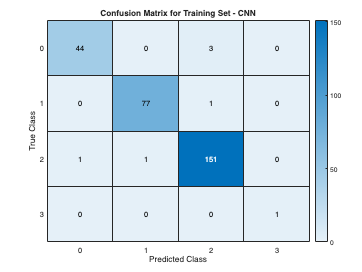

allCategories = unique([y_train; y_validation; y_test]);

y_train_cat = categorical(y_train, allCategories);
y_validation_cat = categorical(y_validation, allCategories);
y_test_cat = categorical(y_test, allCategories);

% Training set predictions and confusion matrix
storeConfusionMatrix(y_train_cat, categorical(YTrainPred, allCategories), 'Training', allCategories,'CNN');

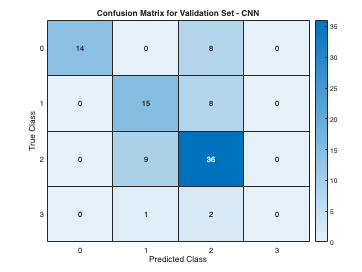


% Validation set predictions and confusion matrix
storeConfusionMatrix(y_validation_cat, categorical(YValPred, allCategories), 'Validation', allCategories,'CNN');

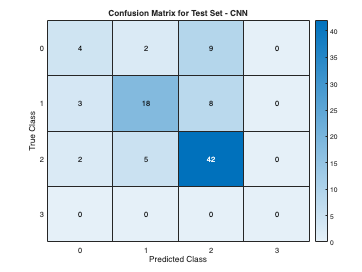


% Test set predictions and confusion matrix
storeConfusionMatrix(y_test_cat, categorical(YTestPred, allCategories), 'Test', allCategories,'CNN');

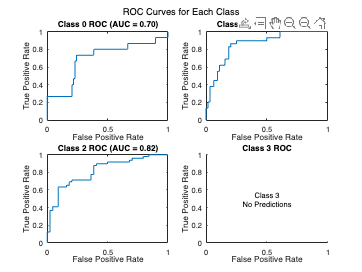

% Plot ROC Curves for Each Class
function plotMulticlassROC(probEstimates, trueLabels, allCategories)
    numClasses = numel(allCategories);
    figure;
    for i = 1:numClasses
        [Xroc, Yroc, ~, AUC] = perfcurve(trueLabels == allCategories(i), probEstimates(:, i), true);
        subplot(2, ceil(numClasses / 2), i);
        plot(Xroc, Yroc);
        title(sprintf('Class %s ROC (AUC = %.2f)', allCategories{i}, AUC));
        xlabel('False Positive Rate');
        ylabel('True Positive Rate');
    end
    sgtitle('ROC Curves for Each Class');
end

% Predict probabilities on the test set
probEstimates = predict(CNN, X_test_reshaped);


allCategories = categories(categorical(y_train));
uniquePredictedCategories = unique(YTestPred);

% Plot ROC curves
figure;
for i = 1:length(allCategories)
    if ismember(allCategories{i}, uniquePredictedCategories)
        [Xroc, Yroc, ~, AUC] = perfcurve(categorical(y_test) == allCategories{i}, probEstimates(:, i), 1);
        subplot(2, ceil(length(allCategories) / 2), i);
        plot(Xroc, Yroc);
        title(sprintf('Class %s ROC (AUC = %.2f)', allCategories{i}, AUC));
        xlabel('False Positive Rate');
        ylabel('True Positive Rate');
    else
        % If the category is not predicted at all, display a warning
        % instead
        subplot(2, ceil(length(allCategories) / 2), i);
        text(0.5, 0.5, sprintf('Class %s\nNo Predictions', allCategories{i}), ...
            'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
        title(sprintf('Class %s ROC', allCategories{i}));
        xlabel('False Positive Rate');
        ylabel('True Positive Rate');
    end
end
sgtitle('ROC Curves for Each Class');

### RNN

% Pre-prcoss train, validation, test X for RNN
X_train_cell = num2cell(X_train, 2); 
X_train_cell = cellfun(@(x) x', X_train_cell, 'UniformOutput', false);  

X_validation_cell = num2cell(X_validation, 2);
X_validation_cell = cellfun(@(x) x', X_validation_cell, 'UniformOutput', false);

X_test_cell = num2cell(X_test, 2);
X_test_cell = cellfun(@(x) x', X_test_cell, 'UniformOutput', false);

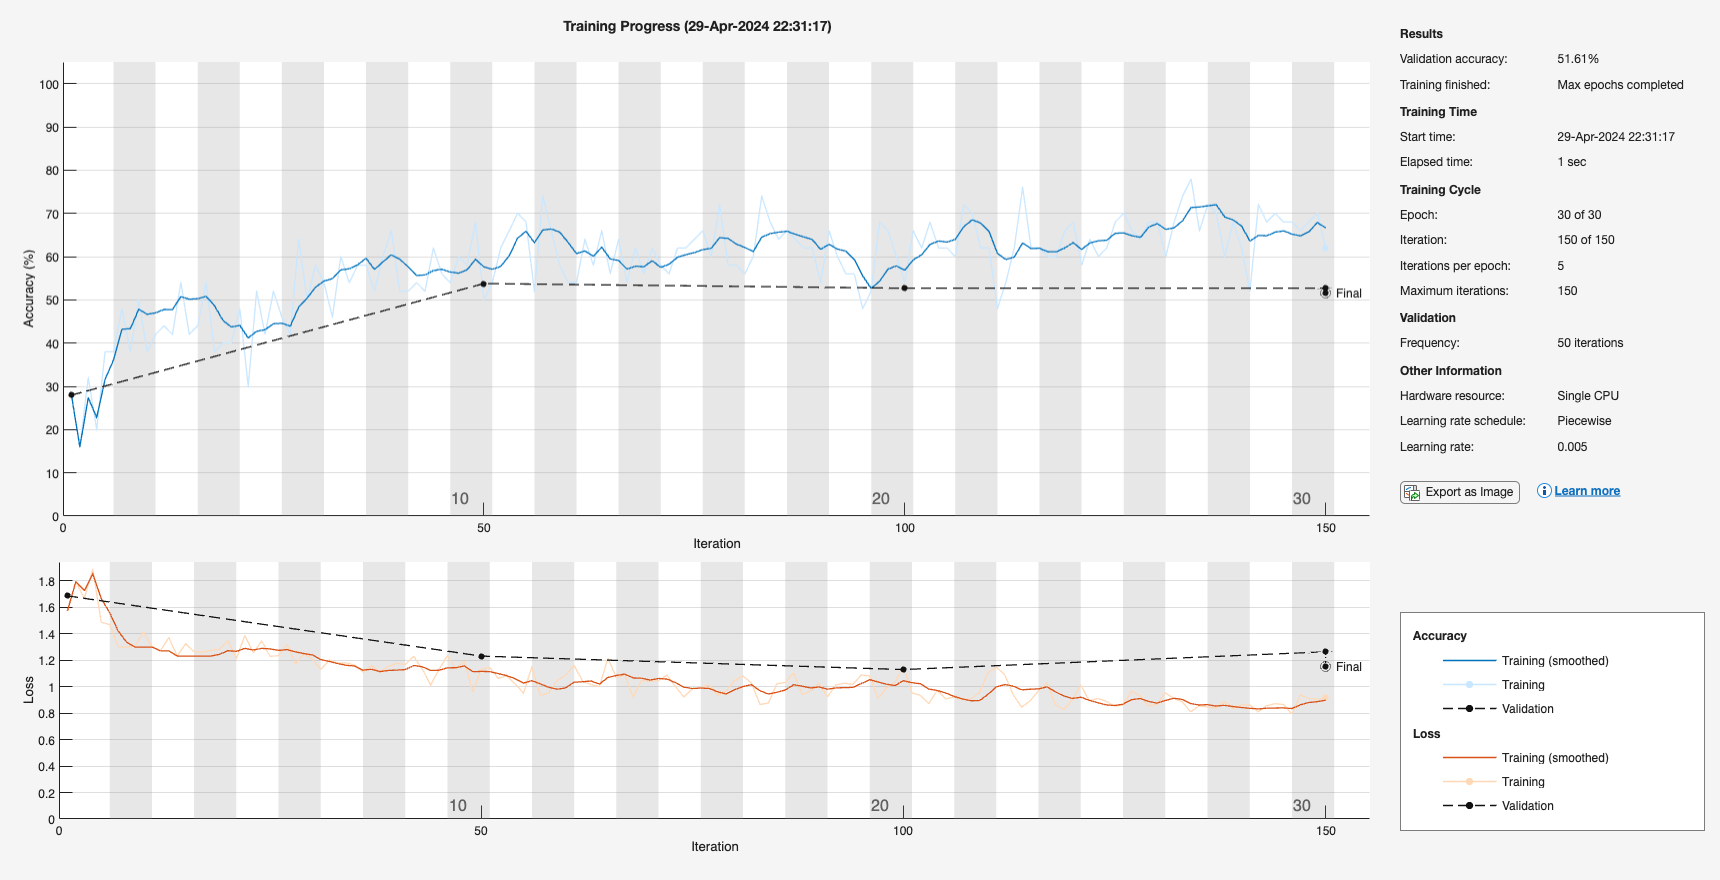

numFeatures = size(X_train, 2);  
numHiddenUnits = 100;            
numClasses = length(unique(y_train));  

% Define the RNN architecture
layers = [ ...
    sequenceInputLayer(numFeatures, 'Name', 'sequence'), ...
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence', 'Name', 'lstm1'), ...
    dropoutLayer(0.2, 'Name', 'dropout1'), ...
    lstmLayer(numHiddenUnits, 'OutputMode', 'sequence', 'Name', 'lstm2'), ...
    dropoutLayer(0.2, 'Name', 'dropout2'), ...
    lstmLayer(numHiddenUnits, 'OutputMode', 'last', 'Name', 'lstm3'), ...
    fullyConnectedLayer(numClasses, 'Name', 'fc'), ...
    batchNormalizationLayer('Name', 'bn'), ...
    softmaxLayer('Name', 'softmax'), ...
    classificationLayer('Name', 'output')];


% Define options for training
options = trainingOptions('adam', ...
    'MaxEpochs', 30, ...
    'MiniBatchSize', 50, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 125, ...
    'LearnRateDropFactor', 0.2, ...
    'Verbose', 0, ...
    'Plots', 'training-progress', ...
    'ValidationData', {X_validation_cell, y_validation});

% Train RNN
RNN = trainNetwork(X_train_cell, y_train, layers, options);

% Display performance metrics
% Training set
YTrainPred = classify(RNN, X_train_cell);
printClassificationMetrics(y_train, YTrainPred, 'Training');


Metrics for Training set:
Accuracy: 0.70
Precision: 0.43
Recall: 0.47
F1 Score: 0.43



% Validation set
YValPred = classify(RNN, X_validation_cell);
printClassificationMetrics(y_validation, YValPred, 'Validation');


Metrics for Validation set:
Accuracy: 0.52
Precision: 0.35
Recall: 0.40
F1 Score: 0.34



% Test set
YTestPred = classify(RNN, X_test_cell);
printClassificationMetrics(y_test, YTestPred, 'Test');


Metrics for Test set:
Accuracy: 0.62
Precision: 0.49
Recall: 0.51
F1 Score: 0.47


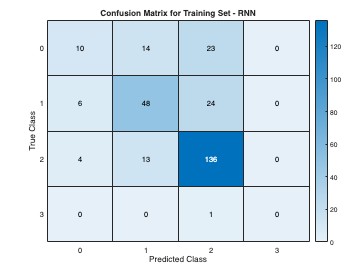

% Confusion Matrix
allCategories = unique([y_train; y_validation; y_test]);

y_train_cat = categorical(y_train, allCategories);
y_validation_cat = categorical(y_validation, allCategories);
y_test_cat = categorical(y_test, allCategories);

% Training set predictions and confusion matrix
storeConfusionMatrix(y_train_cat, categorical(YTrainPred, allCategories), 'Training', allCategories, 'RNN');

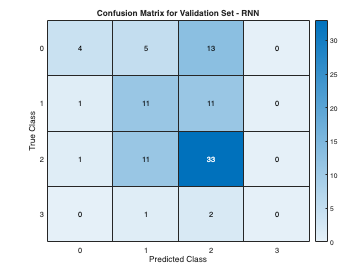


% Validation set predictions and confusion matrix
storeConfusionMatrix(y_validation_cat, categorical(YValPred, allCategories), 'Validation', allCategories, 'RNN');

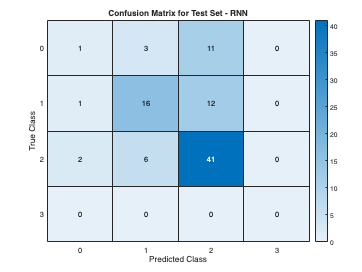


% Test set predictions and confusion matrix
storeConfusionMatrix(y_test_cat, categorical(YTestPred, allCategories), 'Test', allCategories, 'RNN');

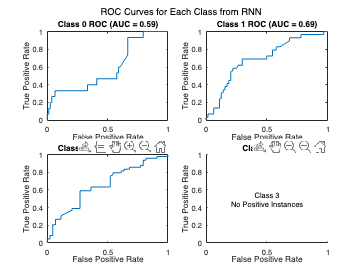

% Plot ROC Curves for Each Class

% Predict probabilities on the test set for RNN
probEstimates = predict(RNN, X_test_cell);

y_test_categorical = categorical(y_test);

allCategories = categories(categorical(y_train));

figure;
for i = 1:length(allCategories)
    trueLabelsBinary = y_test_categorical == allCategories{i};
    
    if any(trueLabelsBinary)
        [Xroc, Yroc, ~, AUC] = perfcurve(trueLabelsBinary, probEstimates(:, i), true);
        subplot(2, ceil(length(allCategories) / 2), i);
        plot(Xroc, Yroc);
        title(sprintf('Class %s ROC (AUC = %.2f)', allCategories{i}, AUC));
        xlabel('False Positive Rate');
        ylabel('True Positive Rate');
    else
        % If the class is not present in the true labels, issue a warning
        subplot(2, ceil(length(allCategories) / 2), i);
        text(0.5, 0.5, sprintf('Class %s\nNo Positive Instances', allCategories{i}), ...
            'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
        title(sprintf('Class %s ROC', allCategories{i}));
        xlabel('False Positive Rate');
        ylabel('True Positive Rate');
    end
end
sgtitle('ROC Curves for Each Class from RNN');

function sents = extract_sentences_distances( ...
    summary, knowledge, n_closer, n_rej, ...
    n_sent_output, emb)

    % split the summary into sentences
    sentences = splitSentences(summary);
    sentences_scores = [];
    for j = 1:length(sentences)
        sentence = sentences(j);
        % convert tokenized document back to 
        % string to make it be able to be 
        % traversed.
        tokens = string(tokenize(sentence));
        % dimension of embedding vector is 
        % 100.
        center = zeros(1,100);
        effective_len = 0;
        for i = 1:length(tokens)
            token = tokens(i);
            if sum(knowledge == tokens(i))>0
                center = center + word2vec(emb, token);
                effective_len = effective_len + 1;
            else
                continue
            end
        end

        if effective_len <= n_rej
            sentences_scores(end+1) = 1;
        else
            center = center/effective_len;
            [closest_words, dists] = vec2word( ...
                emb,center, ...
                n_closer,'Distance','cosine');
            score = mean(dists);
            sentences_scores(end+1) = score;
        end
    end

    % sort scores and sentences "simultaneously"
    [sentences_scores,sortIdx] = sort(sentences_scores,'ascend');
    sentences = sentences(sortIdx);

    sents = sentences(1:n_sent_output);
    
    % there is a problem about overlapping if
    % we directly merge the selected sentences 
    % given the geometric enlargement 
    % direction is unknown and hard to
    % determine.

    % selected_sentences = sentences(1:n_sent_output);
    % sents = join(selected_sentences, " ");
end
function tokens = tokenize(sentence)
    
    % same as what we did when building 
    % embedding dictionary
    tokens = tokenizedDocument(sentence);
    tokens = regexprep(tokens,'[\n\r]+','');
    % get lower case of the string
    tokens = lower(tokens);
    % erace the punctuations in the string
    tokens = erasePunctuation(tokens);
    % remove some other meaningless symbols
    list_symbols = ["[","]","*","''",...
                      "doe","ha","wa"];
    tokens = removeWords(tokens,list_symbols);
    % remove stop words in the strings
    tokens = removeStopWords(tokens);
    % remove everything that is not an English letter
    tokens = regexprep(tokens,'[^a-zA-Z\s]','');

end